# Leitor de arquivo no formato CRFS BIN.

Trata-se de leitor dos principais tipos de dados relacionados às versões 3, 4 e 5 de arquivo no formato CRFS BIN, gerado originalmente pela aplicação Logger, do RFeye. Além do Logger, cujo uso se restringe aos receptores RFeye, é possível gerar arquivo no formato CRFS BIN usando a aplicação appColeta, em desenvolvimento na Gerência Regional nos Estados da Bahia e Sergipe, a qual possibilita captura de dados espectrais por meio de alguns dos analisadores de espectro e receptores que a Agência dispõe.

Versão: **03/03/2021**

function SpecInfo = Fcn_BinFileReaderV4(filename, ReadType, metaData)

    arguments
        filename char
        ReadType char
        metaData struct = []
    end
    
    global FileVersion
    global SpecInfo
    
    fileID = fopen(filename);
    if fileID == -1
        error('Arquivo não encontrado!');
    end
    
    FH_Format  = fread(fileID, 1, 'int32', 32);
    switch FH_Format
        case 21
            FileVersion = 'CRFS BIN v.3';
        case 22
            FileVersion = 'CRFS BIN v.4';
        case 23
            FileVersion = 'CRFS BIN v.5';
        otherwise
            error('Parece não se tratar de um arquivo no formato CRFS BIN (v.3-5).')
    end
    
    switch ReadType
        case {'MetaData', 'SingleFile'}
            SpecInfo = struct('Node',        '', 'ThreadID',    '', ...
                              'MetaData',    [], 'Samples',     [], ...
                              'Data',        {}, 'statsData',   [], ...
                              'FileVersion', '', 'ScriptName',  '', ...
                              'Description', '', 'gps',         [], ...
                              'gpsString',   '', 'gpsFlag',     [], ...
                              'occRelated',  [], 'occFlag',     [], ...
                              'Blocks',      []);
            
            Fcn_MetaDataReader(fileID);
            
            if strcmp(ReadType, 'SingleFile')
                Fcn_SpecDataReader(fileID)
            end
            
        case 'SpecData'
            SpecInfo = metaData(1).Data;
            
            Fcn_SpecDataReader(fileID);
    end

    fclose(fileID);
end

Leitura de **metadados**.

function Fcn_MetaDataReader(fileID)

    global FileVersion
    global SpecInfo
    global GPS
    
    auxStrCell = {};
    gpsSamples = 0;    
    Hostname   = '';
    
    fseek(fileID, 0, 'eof');
    fileSize = ftell(fileID);
    fseek(fileID, 36, 'bof');
    
    ii = 0;
    while ~feof(fileID)
        DBH_ThreadID   = fread(fileID, 1, 'uint32');
        DBH_BytesBlock = fread(fileID, 1, 'uint32');
        DBH_DataType   = fread(fileID, 1,  'int32');
        
        if fileSize-ftell(fileID) < DBH_BytesBlock
            break
        end
        
        if ~isempty(DBH_DataType)
            switch DBH_DataType
                case 3
                    Read_DataType3(fileID, DBH_BytesBlock);
                    
                case 21
                    [Hostname, ~, ScriptName, ~] = Read_DataType21(fileID, DBH_BytesBlock);
                    
                case {22, 24}
                    ii = ii+1;
                    if DBH_DataType == 22;     Description  = Read_DataType22(fileID, DBH_BytesBlock);
                    else                 ; [~, Description] = Read_DataType24(fileID, DBH_BytesBlock);
                    end
                    auxStrCell(ii, 1:2) = {DBH_ThreadID, Description};
                    
                case 40
                    [~, auxGPS] = Read_DataType40(fileID, DBH_BytesBlock);
                    
                    if auxGPS.Status
                        gpsSamples = gpsSamples+1;
                        if gpsSamples == 1
                            GPS = auxGPS;
                        else
                            GPS.Satellites = max(GPS.Satellites, auxGPS.Satellites);
                            GPS.Heading    = max(GPS.Heading, auxGPS.Heading);
                            GPS.Latitude   = GPS.Latitude  + auxGPS.Latitude;
                            GPS.Longitude  = GPS.Longitude + auxGPS.Longitude;
                            GPS.Speed      = max(GPS.Speed, auxGPS.Speed);
                            GPS.Altitude   = GPS.Altitude  + auxGPS.Altitude;
                        end
                    end
                    
                case 41
                    Read_DataType41(fileID, DBH_BytesBlock);
                    
                case 42
                    Read_DataType42(fileID, DBH_BytesBlock);
                    
                case {60, 61, 62, 63, 64, 65, 67, 68, 69}
                    switch DBH_DataType
                        case 60; Read_DataType60(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType);
                        case 61; Read_DataType61(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType);
                        case 62; Read_DataType62(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType);
                        case 63; Read_DataType63(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType);
                        case 64; Read_DataType64(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType);
                        case 65; Read_DataType65(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType);
                        case 67; Read_DataType67(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType, Hostname);
                        case 68; Read_DataType68(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType);
                        case 69; Read_DataType69(fileID, 0, DBH_ThreadID, DBH_BytesBlock, DBH_DataType);
                    end
                    
                otherwise
                    warning(['DataType ' num2str(DBH_DataType) ' pendente de implementação. Favor acionar o servidor Eric (GR08).']);
                    Read_CheckSum(fileID, DBH_BytesBlock)
                    fseek(fileID, DBH_BytesBlock, 'cof');
                    
            end
            Read_DataBlockTrailer(fileID);
            
        end
    end
    
    if gpsSamples
        GPS.Heading   = GPS.Heading   / 100;
        GPS.Latitude  = GPS.Latitude  / (gpsSamples * 1e+6);
        GPS.Longitude = GPS.Longitude / (gpsSamples * 1e+6);
        GPS.Speed     = GPS.Speed     / 1000;
        GPS.Altitude  = GPS.Altitude  / (gpsSamples * 1e+3);
        GPS.Location  = Fcn_FindCity(GPS);
    end
    
    auxRows = size(auxStrCell, 1);
    for jj = auxRows:-1:1
        if ~ismember(auxStrCell{jj,1}, [SpecInfo.ThreadID])
           auxStrCell(jj,:) = [];
        end
    end
    auxStrCell = sortrows(auxStrCell);
    
    [~, auxIndex] = sort([SpecInfo.ThreadID]);
    SpecInfo = SpecInfo(auxIndex);
    
    for kk = 1:length(SpecInfo)
        SpecInfo(kk).Blocks(SpecInfo(kk).Blocks == 0) = [];
        
        SpecInfo(kk).Node = Hostname;
        SpecInfo(kk).FileVersion = FileVersion;
        SpecInfo(kk).ScriptName  = ScriptName;
        
        if ~isempty(auxStrCell)
            SpecInfo(kk).Description = auxStrCell{kk, 2};
        end
        
        if gpsSamples
            SpecInfo(kk).gps       = GPS;
            SpecInfo(kk).gpsString = sprintf('%.6f, %.6f, %.1fm, %d', GPS.Latitude, GPS.Longitude, GPS.Altitude, gpsSamples);
            SpecInfo(kk).gpsFlag   = 0;
        else
            SpecInfo(kk).gpsString = '';
            SpecInfo(kk).gpsFlag   = 1;
        end
    end
end

Leitura de informações de **níveis apenas dos dados de blocos espectrais (incluso ocupação)**.

function Fcn_SpecDataReader(fileID)

    global SpecInfo
    
    global ThreadID
    global Index
    
    for ThreadID = 1:length([SpecInfo.MetaData])
        SpecInfo(ThreadID).Data  = {repmat(datetime([0 0 0 0 0 0], 'Format', 'dd/MM/yyyy HH:mm:ss'), 1, SpecInfo(ThreadID).Samples), ...
                                    zeros(SpecInfo(ThreadID).MetaData.NDATA,                            SpecInfo(ThreadID).Samples, 'single')};        
        
        for Index = 1:SpecInfo(ThreadID).Samples
            switch SpecInfo(ThreadID).MetaData.DataType
                case 60; Read_DataType60(fileID, 1);
                case 61; Read_DataType61(fileID, 1);
                case 62; Read_DataType62(fileID, 1);
                case 63; Read_DataType63(fileID, 1);
                case 64; Read_DataType64(fileID, 1);
                case 65; Read_DataType65(fileID, 1);
                case 67; Read_DataType67(fileID, 1);
                case 68; Read_DataType68(fileID, 1);
                case 69; Read_DataType69(fileID, 1);
            end
        end
    end

end

# Funções auxiliares

**CheckSum Read**

function Read_CheckSum(fileID, DBH_BytesBlock)
    
    global CheckSumAdd
    
    fseek(fileID, -12, 'cof');
    
    auxCheckSum = fread(fileID, DBH_BytesBlock+12, 'uint8');
    CheckSumAdd = uint32(sum(auxCheckSum));
    
    fseek(fileID, -DBH_BytesBlock, 'cof');
    
end

**Data Block Trailer**

function Read_DataBlockTrailer(fileID)

    global CheckSumAdd
    
    DBT_CheckSum  = fread(fileID, 1, 'uint32');
    DBT_EOFMarker = fread(fileID, [1, 4], '*char');
    
    if (DBT_CheckSum ~= CheckSumAdd) | ~strcmp(DBT_EOFMarker, 'UUUU')
        warning('Erro em validação do DataBlocoTrailer (CheckSum ou EOFMarker).');
    end
end

**Análise de erro global e identificação de fluxo.**

function Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, Description)

    global SpecInfo
    
    auxIndex = find([SpecInfo.ThreadID] == DBH_ThreadID);
    for ii = auxIndex
        if isequal(Bin, SpecInfo(ii).MetaData)
            auxIndex = ii;
            break
        else
            auxIndex = [];
        end
    end
    
    if ~isempty(auxIndex)
        SpecInfo(auxIndex).Samples = SpecInfo(auxIndex).Samples + 1;
    else
        auxIndex = length([SpecInfo.ThreadID]) + 1;
        
        SpecInfo(auxIndex).ThreadID = DBH_ThreadID;
        SpecInfo(auxIndex).MetaData = Bin;
        SpecInfo(auxIndex).Samples  = 1;
        
        SpecInfo(auxIndex).Blocks   = zeros(1, 65536);
        
        if ~isempty(Description)
            SpecInfo(auxIndex).Description = Description;
        end
    end
    
    SpecInfo(auxIndex).Blocks(SpecInfo(auxIndex).Samples) = ftell(fileID) - DBH_BytesBlock;
    if SpecInfo(auxIndex).Samples > 65536
        SpecInfo(auxIndex).Blocks = [SpecInfo(auxIndex).Blocks; (ftell(fileID) - DBH_BytesBlock)];
    end

end

# Tipos de dados.

A seguir é apresentada tabela com os tipos de dados gerados pelo RFEye Logger. A versão dos tipos de dados, diga-se, é indicada no início do *script* carregado no Logger, na forma "file_version = 5". E essa informação é recuperada logo no início do arquivo binário, nos campos "FH_Format" (número) e "FH_sFormat" (string), da seguinte forma: FH_Format = 21 (file_version = 3), 22 (file_version = 4) e 23 (file_version = 5).

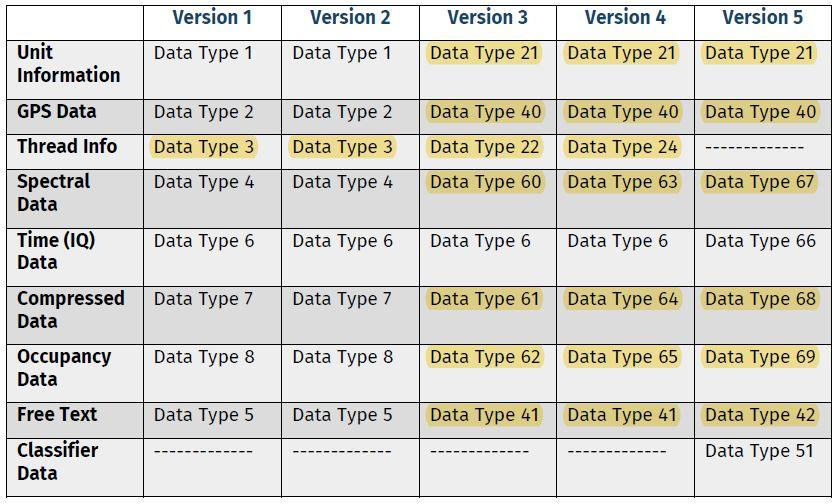

Em destaque os tipos de dados já implantados. 

**DataType 3**

function Text1 = Read_DataType3(fileID, DBH_BytesBlock)
    
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));
end

**DataType 21**

function [Hostname, Text1, Text2, FileNumber] = Read_DataType21(fileID, DBH_BytesBlock)
    
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    Hostname      = deblank(fread(fileID, [1, 16], '*char'));
    Hostname(1:2) = upper(Hostname(1:2));
    Hostname      = erase(Hostname, '_');
    
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));  % unit_info = "Stationary" (ou "Mobile")
    Text1       = erase(Text1, '_');
    
    Text2Length = fread(fileID, 1, 'uint32');
    Text2       = deblank(fread(fileID, [1, Text2Length], '*char'));  % method = "ScriptRFeye2020_v.1"
    Text2       = erase(Text2, '_');
    
    FileNumber  = fread(fileID, 1, 'uint32');
    
end

**DataType 22**

Armazena o campo descrição de cada uma das funções _peak_ e _mean_.

function Text1 = Read_DataType22(fileID, DBH_BytesBlock)
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));  % {'trace mode: Clear/Write ', 'trace mode: Clear/Write, threshold: -85 dBm ', 'trace mode: MaxHold, count = 10 '}
    
end
% DataType 24
function [GroupID, Text1] = Read_DataType24(fileID, DBH_BytesBlock)
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    GroupID     = fread(fileID, 1, 'uint32');
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char')); % {'trace mode: Clear/Write ', 'trace mode: Clear/Write, threshold: -85 dBm ', 'trace mode: MaxHold, count = 10 '}
end

**DataType 40**

function [TimeStamp, GPS] = Read_DataType40(fileID, DBH_BytesBlock)
    
    TimeStamp = [];

    Read_CheckSum(fileID, DBH_BytesBlock);
    
    fseek(fileID, 20, 'cof');
%     % Data block
%     Date_Day   = fread(fileID, 1);
%     Date_Month = fread(fileID, 1);
%     Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
%     
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 5);
%     
%     TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                           Time_Hours, Time_Minutes, Time_Seconds]);
    
    % GPS data
    GPS = struct;
    
%     Date_Day   = fread(fileID, 1);
%     Date_Month = fread(fileID, 1);
%     Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
%     
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 1);
%     
%     GPS.DateTime = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                              Time_Hours, Time_Minutes, Time_Seconds]);
                         
    GPS.Status     = fread(fileID, 1,  'uint8');
    GPS.Satellites = fread(fileID, 1,  'uint8');
    GPS.Heading    = fread(fileID, 1, 'uint16');
    GPS.Latitude   = fread(fileID, 1,  'int32');
    GPS.Longitude  = fread(fileID, 1,  'int32');
    GPS.Speed      = fread(fileID, 1, 'uint32');
    GPS.Altitude   = fread(fileID, 1, 'uint32');
    
end

**DataType 41**

function [TimeStamp, Identifier, Text1] = Read_DataType41(fileID, DBH_BytesBlock)
    
    TimeStamp = [];

    Read_CheckSum(fileID, DBH_BytesBlock);
    
    value1 = ftell(fileID);
    
    fseek(fileID, 12, 'cof');
%     % Data block
%     Date_Day   = fread(fileID, 1);
%     Date_Month = fread(fileID, 1);
%     Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
%     
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 5);
%     
%     TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                           Time_Hours, Time_Minutes, Time_Seconds]);     % Em princípio: 2 blocos
                                                
    Identifier  = deblank(fread(fileID, [1, 32], '*char'));             % 'LOGGER_NAME', 'LOGGER_VERSION'
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));    % 'log_main   ', 'build_version=1.6.7;build_date=Oct  2 2018;build_time=09:11:30;'
    
    value2 = ftell(fileID);
    value2 = value2-value1;
    if value2 < DBH_BytesBlock
        fseek(fileID, DBH_BytesBlock-value2, 'cof');
    end
    
end

**DataType 42**

function [TimeStamp, GroupID, DynamicID, Identifier, Text1] = Read_DataType42(fileID, DBH_BytesBlock)
    
    Read_CheckSum(fileID, DBH_BytesBlock);
    
    % Data block
    value1 = ftell(fileID);
    
    Date_Day   = fread(fileID, 1);
    Date_Month = fread(fileID, 1);
    Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
    
    Time_Hours   = fread(fileID, 1);
    Time_Minutes = fread(fileID, 1);
    Time_Seconds = fread(fileID, 1, 'uint8', 5);
    
    TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
                          Time_Hours, Time_Minutes, Time_Seconds]);     % Em princípio: 2 blocos
    
    GroupID   = fread(fileID, 1, 'uint32');
    DynamicID = fread(fileID, 1, 'uint32');
                                                
    Identifier  = deblank(fread(fileID, [1, 32], '*char'));                      % 'LOGGER_NAME', 'LOGGER_VERSION'
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));             % 'log_main   ', 'build_version=1.6.7;build_date=Oct  2 2018;build_time=09:11:30;'
    value2 = ftell(fileID);
    value2 = value2-value1;
    if value2 < DBH_BytesBlock
        fseek(fileID, DBH_BytesBlock-value2, 'cof');
    end
    
end

**DataType 60**

function Read_DataType60(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType)

    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock);
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',       0, 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode', [], ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.F0 = auxF0 .* 10^expF0;
        Bin.F1 = auxF1 .* 10^expF0;
        
        Bin.AntennaID = fread(fileID, 1, 'uint8');
        GERROR        = fread(fileID, 1,  'int8', 3);
        Bin.TraceMode = fread(fileID, 1);
        NLOOP         = fread(fileID, 1, 'uint8', 1); 
        NPAD          = fread(fileID, 1);
        NTUN          = fread(fileID, 1, 'uint16');
        NAGC          = fread(fileID, 1, 'uint16', 2);
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+Bin.NDATA+NPAD, 'cof');

        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, '')
    
    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 21);
        
        OFFSET = fread(fileID, 1, 'int8');
        NPAD   = fread(fileID, 1);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16', 2);
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData = fread(fileID, [NDATA, 1], 'uint8');
        
        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2 + OFFSET - 127.5;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 61**

function Read_DataType61(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType)
    
    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock);
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',       0, 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode', [], ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.F0 = auxF0 .* 10^expF0;
        Bin.F1 = auxF1 .* 10^expF0;
        
        Bin.AntennaID = fread(fileID, 1, 'uint8');
        GERROR        = fread(fileID, 1,  'int8', 3);
        Bin.TraceMode = fread(fileID, 1);
        NLOOP         = fread(fileID, 1, 'uint8', 1); 
        NPAD          = fread(fileID, 1);
        NTUN          = fread(fileID, 1, 'uint16');
        NAGC          = fread(fileID, 1, 'uint16', 2);
        NCDATA        = fread(fileID, 1, 'uint32');
        Bin.Threshold = fread(fileID, 1, 'int32');
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, '')
    
    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');

        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 21);
        
        OFFSET = fread(fileID, 1, 'int8');
        NPAD   = fread(fileID, 1);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16', 2);
        NCDATA = fread(fileID, 1, 'uint32');
        THRESH = fread(fileID, 1, 'int32');
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData  = ones(NCDATA, 1, 'single') .* 2 .* (127.5 - OFFSET);
        ConvFactor = ((THRESH-1) - OFFSET + 127.5) .* 2;
        CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
        
        ii = 0;
        jj = 0;
        while ii < length(CompressedData)
            ii=ii+1;
            TraceValue = CompressedData(ii);
            if TraceValue == 255
                ii=ii+1;
                kk = CompressedData(ii);
                while kk > 0
                    jj=jj+1;
                    TraceData(jj) = ConvFactor;
                    kk = kk-1;
                end
            elseif TraceValue == 254
                ii=ii+1;
                jj=jj+1;
                TraceData(jj) = CompressedData(ii);
            else
                jj=jj+1;
                TraceData(jj) = TraceValue;
            end
        end
        TraceData(length(TraceData)+1:NDATA) = ConvFactor;
        
        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2 + OFFSET - 127.5;
                
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 62**

function Read_DataType62(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType)
    
    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock);
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',       0, 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode',  0, ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.F0 = auxF0 .* 10^expF0;
        Bin.F1 = auxF1 .* 10^expF0;
        
        Bin.AntennaID = fread(fileID, 1, 'uint8');
        GERROR        = fread(fileID, 1,  'int8', 3);
        Bin.Threshold = fread(fileID, 1, 'int16', 8);
        NPAD          = fread(fileID, 1, 'uint8', 3);
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.NDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, '')
        
    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 29);
        
        NPAD   = fread(fileID, 1, 'uint8', 3);
        NDATA  = fread(fileID, 1, 'uint32');
    
        TraceData = fread(fileID, [NDATA, 1], 'uint8');
        
        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2;
        
        fseek(fileID, NPAD, 'cof'); 
    end
    
end

**DataType 63**

function Read_DataType63(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType)
    
    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock);
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',      [], 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode', [], ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32', 8);
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        NLOOP         = fread(fileID, 1, 'uint32');
        Bin.AntennaID = fread(fileID, 1);
        Bin.TraceMode = fread(fileID, 1);
        Bin.DTYPE     = fread(fileID, 1, 'uint8', 1);
        GERROR        = fread(fileID, 1,  'int8', 2);
        NTUN          = fread(fileID, 1, 'uint16');
        NAGC          = fread(fileID, 1, 'uint16');
        NPAD          = fread(fileID, 1);
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+Bin.NDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, '')

    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 32);
        
        OFFSET = fread(fileID, 1, 'int8', 3);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16');
        NPAD   = fread(fileID, 1);
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData = fread(fileID, [NDATA, 1], 'uint8');

        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2 + OFFSET - 127.5;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 64**

function Read_DataType64(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType)
    
    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock)
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',      [], 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode', [], ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32', 8);
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        NLOOP         = fread(fileID, 1, 'uint32');
        Bin.AntennaID = fread(fileID, 1);
        Bin.TraceMode = fread(fileID, 1);
        Bin.DTYPE     = fread(fileID, 1, 'uint8', 1);
        GERROR        = fread(fileID, 1,  'int8', 2);
        NTUN          = fread(fileID, 1, 'uint16');
        NAGC          = fread(fileID, 1, 'uint16');
        NPAD          = fread(fileID, 1, 'uint8');
        NCDATA        = fread(fileID, 1, 'uint32');
        Bin.Threshold = fread(fileID, 1, 'int32');
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, '')
        
    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 32);
        
        OFFSET = fread(fileID, 1, 'int8', 3);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16');
        NPAD   = fread(fileID, 1);
        NCDATA = fread(fileID, 1, 'uint32');
        THRESH = fread(fileID, 1, 'int32');
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData  = ones(NCDATA, 1, 'single') .* 2 .* (127.5 - OFFSET);
        ConvFactor = ((THRESH-1) - OFFSET + 127.5) .* 2;
        CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
        ii = 0;
        jj = 0;
        while ii < length(CompressedData)
            ii=ii+1;
            TraceValue = CompressedData(ii);
            if TraceValue == 255
                ii=ii+1;
                kk = CompressedData(ii);
                while kk > 0
                    jj=jj+1;
                    TraceData(jj) = ConvFactor;
                    kk = kk-1;
                end
            elseif TraceValue == 254
                ii=ii+1;
                jj=jj+1;
                TraceData(jj) = CompressedData(ii);
            else
                jj=jj+1;
                TraceData(jj) = TraceValue;
            end
        end
        TraceData(length(TraceData)+1:NDATA) = ConvFactor;
        
        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2 + OFFSET - 127.5;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 65**

function Read_DataType65(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType)

    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock);
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',      [], 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode', [], ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32', 4);
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        NLOOP         = fread(fileID, 1, 'uint32');
        Bin.AntennaID = fread(fileID, 1);
        Bin.TraceMode = fread(fileID, 1);
        Bin.DTYPE     = fread(fileID, 1, 'uint16');
        GERROR        = fread(fileID, 1,  'int8', 2);
        NPAD          = fread(fileID, 1);     
        Bin.Threshold = fread(fileID, 1, 'int16', 2);
        Bin.NDATA     = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.NDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, '')
        
    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 32);
        
        NPAD      = fread(fileID, 1, 'uint8', 4);
        Bin.NDATA = fread(fileID, 1, 'uint32');
        
        TraceData = fread(fileID, [Bin.NDATA, 1], 'uint8');
        
        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2;
            
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 67**

function Read_DataType67(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType, Hostname)
    
    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock);
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',      [], 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode', [], ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);
      
        fseek(fileID, 20, 'cof');
        TextLength  = fread(fileID, 1, 'uint32');
        Description = deblank(fread(fileID, [1, TextLength], '*char'));
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.Resolution = fread(fileID, 1, 'uint32', 8);
        NLOOP          = fread(fileID, 1, 'uint32');
        Bin.AntennaID  = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.DTYPE      = fread(fileID, 1, 'uint8', 1);
        GERROR         = fread(fileID, 1,  'int8', 1);
        
%%      Capturar informação do Detector gerada pelo appColeta p/ monitorações com
%%      analisadores de espectro e receptores (em especial o EB500).
        if contains(Hostname, 'RFeye', 'IgnoreCase', true)
            fseek(fileID, 1, 'cof');
        else
            Bin.Detector = fread(fileID, 1);
        end
        
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1);
        Bin.NDATA      = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+Bin.NDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, Description)
        
    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        
        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID,TextLength+31,'cof');
        
        OFFSET     = fread(fileID, 1, 'int8', 3);
        NTUN       = fread(fileID, 1, 'uint16');
        NAGC       = fread(fileID, 1, 'uint16');
        NPAD       = fread(fileID, 1);
        NDATA      = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData = fread(fileID, [NDATA, 1], 'uint8');
        
        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2 + OFFSET - 127.5;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 68**

function Read_DataType68(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType)
    
    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock);
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',      [], 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode', [], ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);

        fseek(fileID, 20, 'cof');
        
        TextLength  = fread(fileID, 1, 'uint32');
        Description = deblank(fread(fileID, [1, TextLength], '*char'));
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.Resolution = fread(fileID, 1, 'uint32', 8);
        NLOOP          = fread(fileID, 1, 'uint32');
        Bin.AntennaID  = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.DTYPE      = fread(fileID, 1, 'uint8', 1);
        GERROR         = fread(fileID, 1,  'int8', 2);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1);                                  % Number of bytes of padding (0, 1, 2 or 3)
        NCDATA         = fread(fileID, 1, 'uint32');
        Bin.Threshold  = fread(fileID, 1, 'int32');
        Bin.NDATA      = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, Description)
        
    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        
        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID,TextLength+31,'cof');
        
        OFFSET = fread(fileID, 1, 'int8', 3);
        NTUN   = fread(fileID, 1, 'uint16');
        NAGC   = fread(fileID, 1, 'uint16');
        NPAD   = fread(fileID, 1);
        NCDATA = fread(fileID, 1, 'uint32');
        THRESH = fread(fileID, 1, 'int32');
        NDATA  = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData  = ones(NCDATA, 1, 'single') .* 2 .* (127.5 - OFFSET);
        ConvFactor = ((THRESH-1) - OFFSET + 127.5) .* 2;
        CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
        ii = 0;
        jj = 0;
        while ii < length(CompressedData)
            ii=ii+1;
            TraceValue = CompressedData(ii);
            if TraceValue == 255
                ii=ii+1;
                kk = CompressedData(ii);
                while kk > 0
                    jj=jj+1;
                    TraceData(jj) = ConvFactor;
                    kk = kk-1;
                end
            elseif TraceValue == 254
                ii=ii+1;
                jj=jj+1;
                TraceData(jj) = CompressedData(ii);
            else
                jj=jj+1;
                TraceData(jj) = TraceValue;
            end
        end
        TraceData(length(TraceData)+1:NDATA) = ConvFactor;
        
        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2 + OFFSET - 127.5;

        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 69**

function Read_DataType69(fileID, Flag, DBH_ThreadID, DBH_BytesBlock, DBH_DataType)
    
    global SpecInfo
    global ThreadID
    global Index
    
    if ~Flag
        Read_CheckSum(fileID, DBH_BytesBlock);
        
        Bin = struct('DataType', DBH_DataType, 'ThreadID', DBH_ThreadID, ...
                     'F0',         [], 'F1',        [], ...
                     'DTYPE',      [], 'NDATA',     [], ...
                     'Resolution', [], 'SweepTime', [], ...
                     'Threshold',  [], 'TraceMode', [], ...
                     'Detector',   [], 'AntennaID', [], ...
                     'NLOOP', []);

        fseek(fileID, 20, 'cof');
      
        TextLength  = fread(fileID, 1, 'uint32');
        Description = deblank(fread(fileID, [1, TextLength], '*char'));
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F0      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        IntegerPart = fread(fileID, 1, 'uint16');
        DecimalPart = fread(fileID, 1, 'int32');
        Bin.F1      = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.Resolution = fread(fileID, 1, 'uint32', 4);
        Bin.NLOOP          = fread(fileID, 1, 'uint32');
        Bin.AntennaID  = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.DTYPE      = fread(fileID, 1, 'uint16');
        GERROR         = fread(fileID, 1,  'int8', 2);
        NPAD           = fread(fileID, 1);      
        Bin.Threshold  = fread(fileID, 1, 'int16', 2);
        Bin.NDATA      = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.NDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, DBH_ThreadID, DBH_BytesBlock, Description)
        
    else
        fseek(fileID, SpecInfo(ThreadID).Blocks(Index), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        
        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID, TextLength+31,'cof');
        NPAD       = fread(fileID, 1, 'uint8', 4);      
        NDATA      = fread(fileID, 1, 'uint32');
        
        TraceData = fread(fileID, [NDATA, 1], 'uint8');
        
        SpecInfo(ThreadID).Data{1}(Index)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ThreadID).Data{2}(:,Index) = single(TraceData)./2;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end